23.51

close all
clc
clear

mot.k = 5.2;
mot.T = 0.03;

s = tf('s');
P = mot.k / (s * (mot.T * s + 1));
pid.ki = 13.0;
pid.kd = 0.02;
pid.tl = 0.001;
C = minreal(1 + pid.ki / s + pid.kd * s / (pid.tl * s + 1), 1e-6);

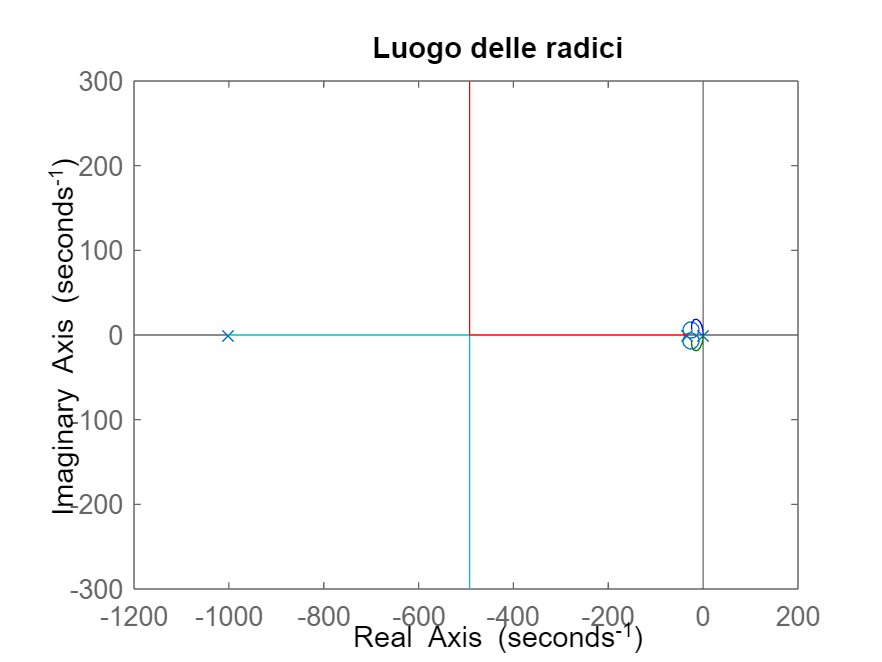

figure(1)
rlocus(P * C)
title("Luogo delle radici")

Per ogni k positivo, tutti i poli del sistema in catena chiusa sono nel semipiano complesso sinistro, dunque ho BIBO stabilità

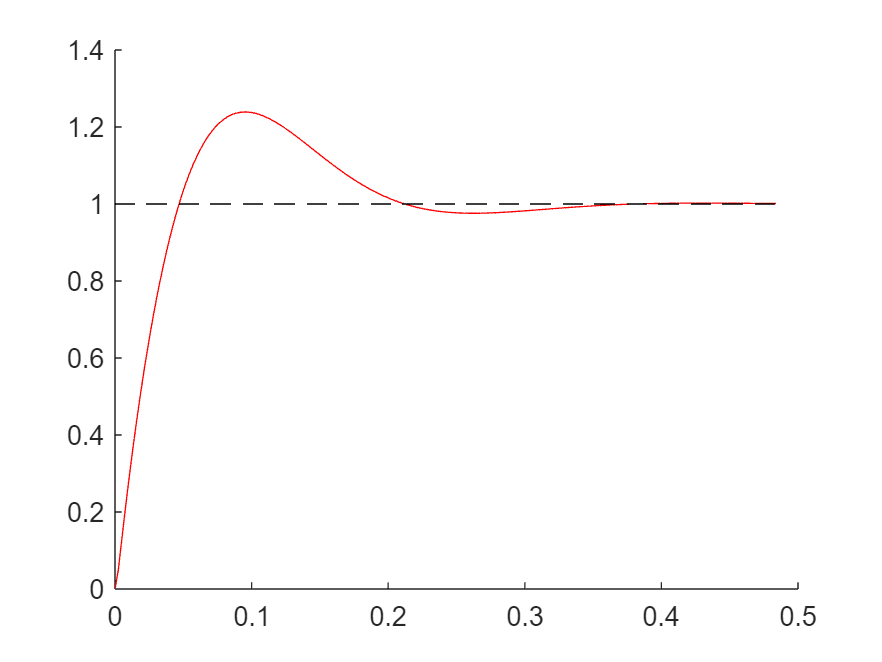

pid.kp = 9;
T = minreal(feedback(pid.kp * C * P, 1), 1e-6);
[y, t] = step(T);
close all
figure(2)
hold on
plot(t, y, "r")
plot([t(1), t(end)], [1, 1], "k--")

infos = stepinfo(T, "SettlingTimeThreshold", 0.01);

infos.Overshoot

ans = 23.8958

infos.SettlingTime

ans = 0.3285

Ts = 0.005;
wbar = 100;
opt = c2dOptions('Method', 'tustin', 'PrewarpFrequency', wbar);
Cd = c2d(pid.kp * C, Ts, opt);

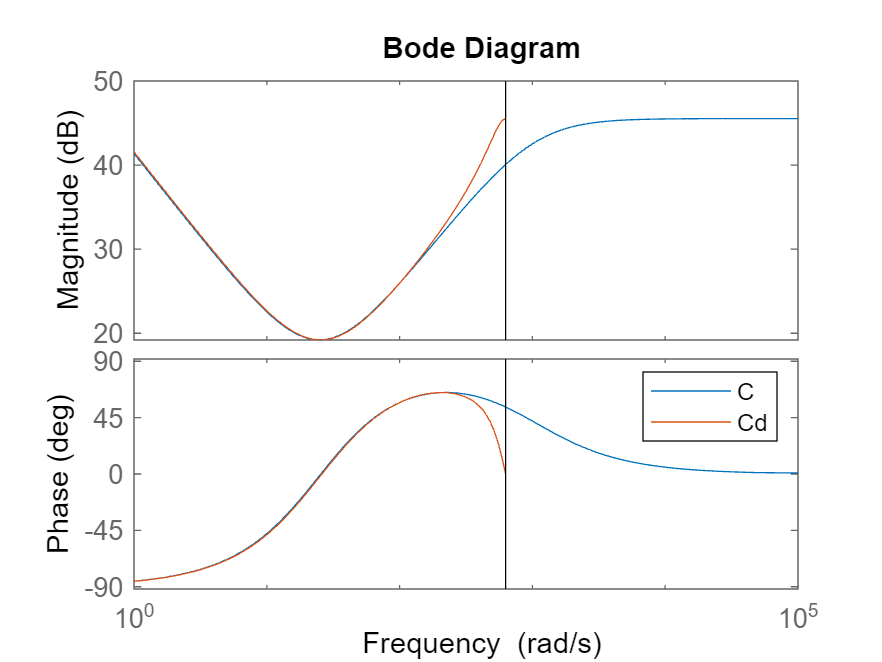

close all
figure(3)
hold on
bode(pid.kp * C)
bode(Cd)
legend("C", "Cd")

wt = 500;
A1 = -20 * log10(bode(pid.kp * C, wbar) / bode(Cd, wbar))

A1 = -1.9287e-15

A2 = -20 * log10(bode(pid.kp * C, wt) / bode(Cd, wt))

A2 = 4.6193


ph1 = (angle(freqresp(Cd, wbar)) - angle(freqresp(pid.kp * C, wbar))) * 180 / pi

ph1 = 0

ph2 = (angle(freqresp(Cd, wt)) - angle(freqresp(pid.kp * C, wt))) * 180 / pi

ph2 = -19.9430

tc = 0:0.001:0.1;
sinc1 = sin(wbar * tc);
yc1 = lsim(pid.kp * C, sinc1, tc);
sinc2 = sin(wt * tc);
yc2 = lsim(pid.kp * C, sinc2, tc);

td = 0:Ts:0.1;
sind1 = sin(wbar * td);
yd1 = lsim(Cd, sind1, td);
sind2 = sin(wt * td);
yd2 = lsim(Cd, sind2, td);

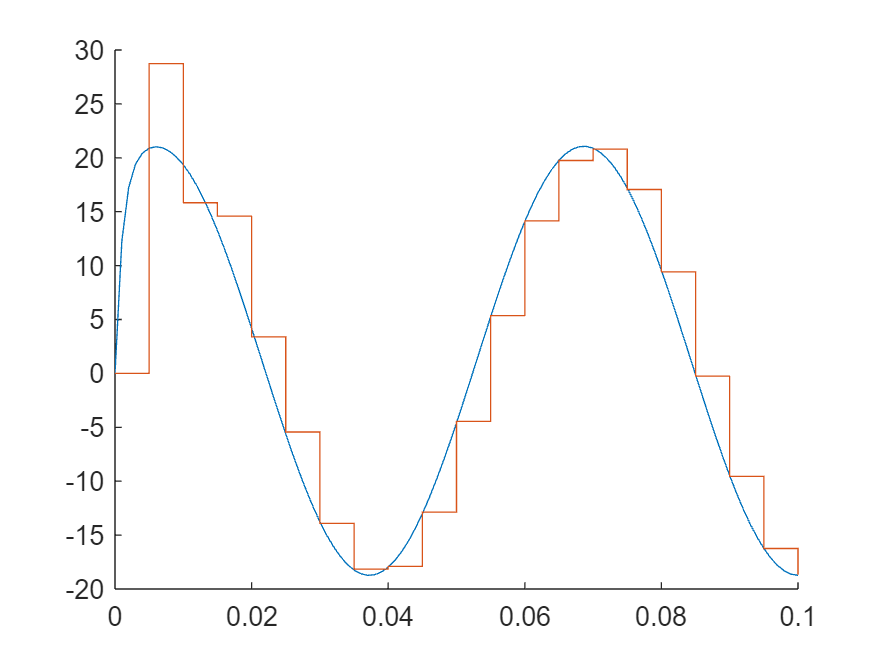

close all
figure(5)
hold on
plot(tc, yc1)
stairs(td, yd1)

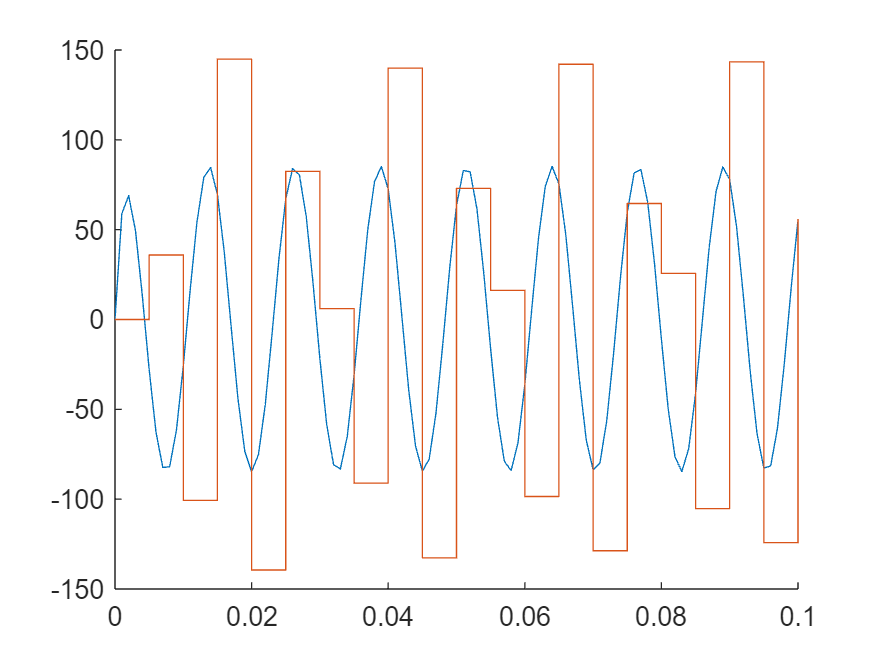

close all
figure(6)
hold on
plot(tc, yc2)
stairs(td, yd2)

00.18